% Mori-Tanaka
% imposed strain rate
  E  =[0 1 0;1 0 0;0 0 0];
  EI = Inva(E);

% clasts
  n = 100; 
  [a,ang]= RandAANG(5,n);
  q = Qvec(ang); 
  aa=ones(3,n);
  r =10;
  
  phi=0:0.1:1;
  
  vis_MT1 = zeros(1,numel(phi));
  vis_MT2 = zeros(1,numel(phi));
  vis_MT3 = zeros(1,numel(phi));
%   vis_MT4 = zeros(1,numel(phi));
%   vis_MT5 = zeros(1,numel(phi));

  Em1 = zeros(1,numel(phi));
  Em2 = zeros(1,numel(phi));
  Em3 = zeros(1,numel(phi));
%   Em4 = zeros(1,numel(phi));
%   Em5 = zeros(1,numel(phi));

  Sm1 = zeros(1,numel(phi));
  Sm2 = zeros(1,numel(phi));
  Sm3 = zeros(1,numel(phi));
%   Sm4 = zeros(1,numel(phi));
%   Sm5 = zeros(1,numel(phi));

  e1 = zeros(n,numel(phi));
  e2 = zeros(n,numel(phi));
  e3 = zeros(n,numel(phi));
%   e4 = zeros(n,numel(phi));
%   e5 = zeros(n,numel(phi));

  s1 = zeros(n,numel(phi));
  s2 = zeros(n,numel(phi));
  s3 = zeros(n,numel(phi));
%   s4 = zeros(n,numel(phi));
%   s5 = zeros(n,numel(phi));

  vis1 = zeros(n,numel(phi));
  vis2 = zeros(n,numel(phi));
  vis3 = zeros(n,numel(phi));

  vism1 = zeros(1,numel(phi));
  vism2 = zeros(1,numel(phi));
  vism3 = zeros(1,numel(phi));
  tic
  for kk=1:numel(phi)
      % spherical clasts
      [S_bar,~,Em,Sm,e,s,vis,vis0]=MT_homogenization(E,n,aa,q,r.*ones(n,1),1,ones(n,1),1,phi(kk));
      vis_MT1(kk)=Inva(S_bar)/EI/2;
      Em1(kk)=Inva(Em);
      Sm1(kk)=Inva(Sm);
      vis1(:,kk) = vis;
      vism1(kk)= vis0;
      for rr=1:n
          e1(rr,kk)=Inva(e(:,:,rr));
          s1(rr,kk)=Inva(s(:,:,rr));
      end
  end
  toc

Elapsed time is 1.916883 seconds.



  tic
  for kk=1:numel(phi)
      % spherical clasts
      [S_bar,~,Em,Sm,e,s,vis,vis0]=MT_homogenization(E,n,aa,q,r.*ones(n,1),1,ones(n,1),3,phi(kk));
      vis_MT2(kk)=Inva(S_bar)/EI/2;
      Em2(kk)=Inva(Em);
      Sm2(kk)=Inva(Sm);
      vis2(:,kk) = vis;
      vism2(kk)= vis0;
      for rr=1:n
          e2(rr,kk)=Inva(e(:,:,rr));
          s2(rr,kk)=Inva(s(:,:,rr));
      end
  end
  toc

Elapsed time is 5.556794 seconds.



  tic
  for kk=1:numel(phi)
      % spherical clasts
      [S_bar,~,Em,Sm,e,s,vis,vis0]=MT_homogenization(E,n,aa,q,r.*ones(n,1),1,ones(n,1),10,phi(kk));
      vis_MT3(kk)=Inva(S_bar)/EI/2;
      Em3(kk)=Inva(Em);
      Sm3(kk)=Inva(Sm);
      vis3(:,kk) = vis;
      vism3(kk)= vis0;
      for rr=1:n
          e3(rr,kk)=Inva(e(:,:,rr));
          s3(rr,kk)=Inva(s(:,:,rr));
      end
  end
  toc

Elapsed time is 8.693073 seconds.


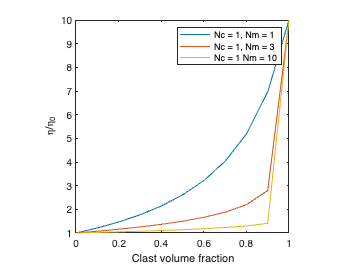


%   tic
%   for kk=1:numel(phi)
%       % spherical clasts
%       [S_bar,~,~,~,~,~,~,~]=MT_homogenization(E,n,aa,q,r.*ones(n,1),1,ones(n,1),10,phi(kk));
%       vis_MT3(kk)=Inva(S_bar)/EI/2;
%   end
%   toc

  figure('Name','Mori_Tanaka Results')
  plot(phi,vis_MT1,phi,vis_MT2,phi,vis_MT3)
  xlim([0 1])
  ylim([1,r])
  axis square
  xlabel('Clast volume fraction')
  ylabel('\eta/\eta_0')
  legend('Nc = 1, Nm = 1','Nc = 1, Nm = 3','Nc = 1 Nm = 10')